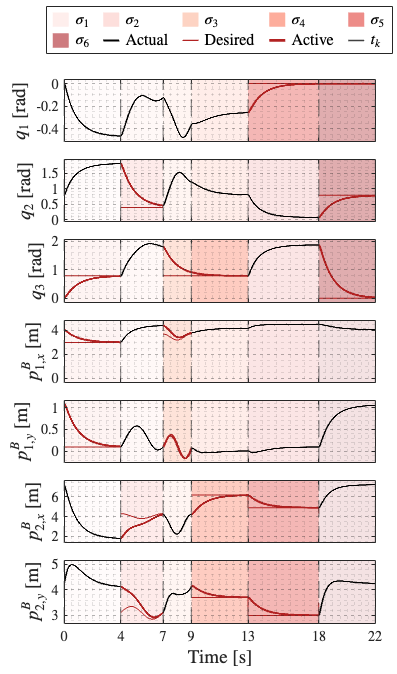

%% ============================================================
%  One-column manuscript figure: 3R planar robot time evolution
%  Requires variables from Simulink output:
%      out.tout, out.q, out.qd, out.b1, out.b2, out.b1d, out.b2d
%
%  Output:
%      3r_time_evolution_one_column.pdf
%% ============================================================

close all; clc;

%% ================== CONFIGURATION ==================
outputFile = '3r_time_evolution_one_column.pdf';

lineWidthActual  = 0.95;
lineWidthDesired = 0.55;
lineWidthActive  = 1.35;
lineWidthSwitch  = 0.75;

fontSizeAxes   = 8.5;
fontSizeLabels = 12.0;
fontSizeLegend = 10.0;

bgOpacityInactive = 0.12;
bgOpacityActive   = 0.34;

% One-column paper size, in inches.
figWidth  = 3.45;
figHeight = 5.85;

% Use LaTeX everywhere.
set(groot, 'defaultTextInterpreter', 'latex');
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');

%% ================== LOAD DATA FROM SIMULINK ==================
tvec = out.tout(:).';

q   = squeeze(out.q);
qd  = squeeze(out.qd);
pb1 = squeeze(out.b1);
pb2 = squeeze(out.b2);
b1d = squeeze(out.b1d);
b2d = squeeze(out.b2d);

% Make sure signals have shape rows x samples.
q   = ensureRows(q,   3);
qd  = ensureRows(qd,  3);
pb1 = ensureRows(pb1, 2);
pb2 = ensureRows(pb2, 2);
b1d = ensureRows(b1d, 2);
b2d = ensureRows(b2d, 2);

%% ================== ACTIVATION INTERVALS ==================
activeIntervals = [
    0, 4;
    4, 7;
    7, 9;
    9, 13;
    13, 18;
    18, 22;
];

activeVars = {
    {'q3','pb1x','pb1y'};
    {'q2','pb2x','pb2y'};
    {'q3','pb1x','pb1y'};
    {'q3','pb2x','pb2y'};
    {'q1','pb2x','pb2y'};
    {'q1','q2','q3'};
};

switchTimes = unique(activeIntervals(:));

% MELD interval colors: sigma_1 to sigma_6.
% This palette keeps the red family from your MATLAB animation, but is
% softened for a one-column paper figure.
meldColors = [
    253, 224, 221;   % sigma_1
    252, 197, 192;   % sigma_2
    252, 174, 145;   % sigma_3
    251, 106,  74;   % sigma_4
    222,  45,  38;   % sigma_5
    165,  15,  21;   % sigma_6
] / 255;

meldLabels = {
    '$\sigma_1$', ...
    '$\sigma_2$', ...
    '$\sigma_3$', ...
    '$\sigma_4$', ...
    '$\sigma_5$', ...
    '$\sigma_6$'
};

%% ================== VARIABLES TO PLOT ==================
allVars = {
    struct('data', q,   'des', qd,  'idx', 1, 'label', '$q_1$ [rad]',        'name', 'q1');
    struct('data', q,   'des', qd,  'idx', 2, 'label', '$q_2$ [rad]',        'name', 'q2');
    struct('data', q,   'des', qd,  'idx', 3, 'label', '$q_3$ [rad]',        'name', 'q3');
    struct('data', pb1, 'des', b1d, 'idx', 1, 'label', '$p^B_{1,x}$ [m]',    'name', 'pb1x');
    struct('data', pb1, 'des', b1d, 'idx', 2, 'label', '$p^B_{1,y}$ [m]',    'name', 'pb1y');
    struct('data', pb2, 'des', b2d, 'idx', 1, 'label', '$p^B_{2,x}$ [m]',    'name', 'pb2x');
    struct('data', pb2, 'des', b2d, 'idx', 2, 'label', '$p^B_{2,y}$ [m]',    'name', 'pb2y');
};

%% ================== FIGURE ==================
fig = figure( ...
    'Color', 'w', ...
    'Units', 'inches', ...
    'Position', [1 1 figWidth figHeight], ...
    'PaperUnits', 'inches', ...
    'PaperPosition', [0 0 figWidth figHeight], ...
    'PaperSize', [figWidth figHeight]);

tl = tiledlayout(fig, 7, 1, ...
    'TileSpacing', 'compact', ...
    'Padding', 'compact');

axList = gobjects(numel(allVars), 1);
hPatchLegend = gobjects(6, 1);

for i = 1:numel(allVars)
    ax = nexttile(tl);
    axList(i) = ax;

    showXLabel = i == numel(allVars);

    [hPatch, ~, ~, ~] = plotVectorComponentForPaper( ...
        ax, ...
        tvec, ...
        allVars{i}.data, ...
        allVars{i}.des, ...
        allVars{i}.idx, ...
        allVars{i}.label, ...
        allVars{i}.name, ...
        showXLabel, ...
        activeIntervals, ...
        activeVars, ...
        switchTimes, ...
        meldColors, ...
        bgOpacityInactive, ...
        bgOpacityActive, ...
        lineWidthActual, ...
        lineWidthDesired, ...
        lineWidthActive, ...
        lineWidthSwitch, ...
        fontSizeAxes, ...
        fontSizeLabels);

    if i == 1
        hPatchLegend = hPatch;
    end
end

%% ================== COMPACT LEGEND ==================
% Dummy handles for legend.
hold(axList(1), 'on');

hMeld = gobjects(6, 1);
for k = 1:6
    hMeld(k) = patch(axList(1), NaN, NaN, meldColors(k,:), ...
        'FaceAlpha', 0.55, ...
        'EdgeColor', 'none', ...
        'DisplayName', meldLabels{k});
end

hActual = plot(axList(1), NaN, NaN, ...
    'k-', ...
    'LineWidth', lineWidthActual + 0.3, ...
    'DisplayName', 'Actual');

hDesired = plot(axList(1), NaN, NaN, ...
    '-', ...
    'Color', [178 34 34]/255, ...
    'LineWidth', lineWidthDesired + 0.2, ...
    'DisplayName', 'Desired');

hActive = plot(axList(1), NaN, NaN, ...
    '-', ...
    'Color', [178 34 34]/255, ...
    'LineWidth', lineWidthActive + 0.3, ...
    'DisplayName', 'Active');

hSwitch = plot(axList(1), NaN, NaN, ...
    '--', ...
    'Color', [0.25 0.25 0.25], ...
    'LineWidth', lineWidthSwitch + 0.2, ...
    'DisplayName', '$t_k$');

lg = legend(axList(1), ...
    [hMeld(:); hActual; hDesired; hActive; hSwitch], ...
    [meldLabels, {'Actual', 'Desired', 'Active', '$t_k$'}], ...
    'Orientation', 'horizontal', ...
    'NumColumns', 5, ...
    'FontSize', fontSizeLegend, ...
    'Interpreter', 'latex', ...
    'Box', 'on');

lg.Layout.Tile = 'north';
lg.ItemTokenSize = [10, 6];

%% ================== EXPORT ==================
% Vector PDF export.
set(fig, 'Renderer', 'painters');

exportgraphics(fig, outputFile, ...
    'ContentType', 'vector', ...
    'BackgroundColor', 'white');


disp(['Saved PDF figure: ', outputFile]);

Saved PDF figure: 3r_time_evolution_one_column.pdf



%% ============================================================
%  FUNCTIONS
%% ============================================================

function x = ensureRows(x, nRows)
    x = squeeze(x);

    if size(x, 1) ~= nRows && size(x, 2) == nRows
        x = x.';
    end

    if size(x, 1) ~= nRows
        error('Signal has wrong shape. Expected %d rows, got %d.', nRows, size(x,1));
    end
end

function [hPatches, hActual, hDesired, hActive] = plotVectorComponentForPaper( ...
    ax, time, data, desData, idx, yLabelStr, varName, showXLabel, ...
    activeIntervals, activeVars, switchTimes, meldColors, ...
    bgOpacityInactive, bgOpacityActive, ...
    lineWidthActual, lineWidthDesired, lineWidthActive, lineWidthSwitch, ...
    fontSizeAxes, fontSizeLabels)

    axes(ax);
    hold(ax, 'on');

    colorActual  = [0 0 0];
    colorDesired = [178 34 34] / 255;
    colorActive  = [178 34 34] / 255;
    colorSwitch  = [0.25 0.25 0.25];

    y = data(idx, :);
    yd = desData(idx, :);

    finiteVals = [y(isfinite(y)), yd(isfinite(yd))];

    if isempty(finiteVals)
        yMin = -1;
        yMax = 1;
    else
        yMin = min(finiteVals);
        yMax = max(finiteVals);
    end

    padding = 0.08 * max(yMax - yMin, 1e-8);
    yLimits = [yMin - padding, yMax + padding];

    % Background MELD intervals.
    hPatches = gobjects(size(activeIntervals,1), 1);

    for k = 1:size(activeIntervals,1)
        tStart = activeIntervals(k,1);
        tEnd   = activeIntervals(k,2);

        if ismember(varName, activeVars{k})
            alpha = bgOpacityActive;
        else
            alpha = bgOpacityInactive;
        end

        hPatches(k) = patch(ax, ...
            [tStart tEnd tEnd tStart], ...
            [yLimits(1) yLimits(1) yLimits(2) yLimits(2)], ...
            meldColors(k,:), ...
            'FaceAlpha', alpha, ...
            'EdgeColor', 'none', ...
            'HandleVisibility', 'off');
    end

    % Actual full trajectory.
    hActual = plot(ax, time, y, ...
        'Color', colorActual, ...
        'LineWidth', lineWidthActual, ...
        'HandleVisibility', 'off');

    % Active portions and desired trajectory.
    hDesired = gobjects(size(activeIntervals,1), 1);
    hActive  = gobjects(size(activeIntervals,1), 1);

    for k = 1:size(activeIntervals,1)
        tStart = activeIntervals(k,1);
        tEnd   = activeIntervals(k,2);

        if ismember(varName, activeVars{k})
            mask = time >= tStart & time <= tEnd;

            hActive(k) = plot(ax, time(mask), y(mask), ...
                'Color', colorActive, ...
                'LineWidth', lineWidthActive, ...
                'HandleVisibility', 'off');

            hDesired(k) = plot(ax, time(mask), yd(mask), ...
                '-', ...
                'Color', colorDesired, ...
                'LineWidth', lineWidthDesired, ...
                'HandleVisibility', 'off');
        end
    end

    % Switching instants.
    for s = 1:numel(switchTimes)
        xline(ax, switchTimes(s), ...
            '--', ...
            'Color', colorSwitch, ...
            'LineWidth', lineWidthSwitch, ...
            'Alpha', 0.55, ...
            'HandleVisibility', 'off');
    end

    % Formatting.
    box(ax, 'on');
    grid(ax, 'on');

    ax.GridLineStyle = ':';
    ax.GridAlpha = 0.35;
    ax.MinorGridLineStyle = ':';
    ax.MinorGridAlpha = 0.12;
    ax.XMinorGrid = 'on';
    ax.YMinorGrid = 'on';

    ax.FontSize = fontSizeAxes;
    ax.TickLabelInterpreter = 'latex';
    ax.LineWidth = 0.55;
    ax.TickDir = 'in';
    ax.Layer = 'top';

    ylabel(ax, yLabelStr, ...
        'Interpreter', 'latex', ...
        'FontSize', fontSizeLabels);

    xlim(ax, [time(1), time(end)]);
    ylim(ax, yLimits);

    xticks(ax, unique([time(1), switchTimes(:).', time(end)]));

    if showXLabel
        xlabel(ax, 'Time [s]', ...
            'Interpreter', 'latex', ...
            'FontSize', fontSizeLabels);
    else
        ax.XTickLabel = [];
    end

    hold(ax, 'off');
end